clear
close all
hold off


En este código se va a implementar el método de Quasi-Newton para dos dimensiones. A continuación se determinan las condiciones iniciales y las constantes.

N=4; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo
k=1.1; %Valor para el line search inexacto
H_0(:,:,1)=eye(2); %Hessiano inicial para la iteración

c1=10^-4;
c2=0.9; %Parámetros para el line search (c2=0.7 da solución rápida, valores más bajos resultan en un tiempo de computación notable)

colors=["ob","ok","or","om"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
plot(c0(1,1),c0(2,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
i=1;
I=eye(2);

A continuación se pasa al cálculo de la posición de los centros. Se hace uso de un método de line-search inexacto con las condiciones Strong Wolfe.

while mod_rc>0.001

    if i==iteration
        break
    end
    grad_centr(:,i)=gradient_point2D(c(:,i),t(i),N,D,S,w0);
    %Posición de los robots
    pos_rob(:,1:N,i)=posicion_robots(c0,N,D,w0,i,t);
    alpha1=1; 
    p(:,i)=-H_0(:,:,i)*grad_centr(:,i); %Dirección descendente
    steplengthParam=[c1,c2,alpha1,k];
    [alpha(i),u(i)]=alpha_strongWolfe(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0);        
    c(:,i+1)=c(:,i)-alpha(i)*H_0(:,:,i)*grad_centr(:,i);
    grad_centr(:,i+1)=gradient_point2D(c(:,i+1),t(i+1),N,D,S,w0);
    x_k1=c(:,i+1);
    x_k=c(:,i);
    s_k=x_k1-x_k;
    q_k=grad_centr(:,i+1)-grad_centr(:,i);
    B_k=(I-(s_k*q_k'/(q_k'*s_k)))*H_0(:,:,i)*(I-(q_k*s_k'/(q_k'*s_k)))+s_k*s_k'/(q_k'*s_k); %Hessiano invertido
    H_0(:,:,i+1)=B_k;       

    c0=c(:,i);
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
    i=i+1;
end
u

u =     14     1     1     1    28     1     1     1


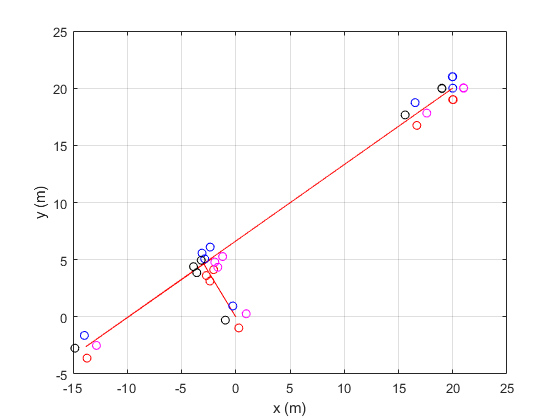

%Representación del centro
plot(c(1,:),c(2,:),'.r')
for g=1:N
    for z=1:length(mod_r_c)
        plot(pos_rob(1,g,z),pos_rob(2,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
grid on
hold off

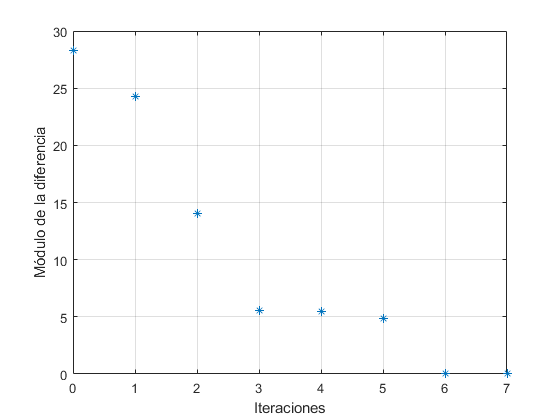

plot(0:length(mod_r_c)-1,mod_r_c,"*")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 1.1066e-05

c0

c0 = 	1.0e+-5 *

   -0.9937
    0.4871


u

u =     14     1     1     1    28     1     1     1


num_iteraciones=sum(u) %número de iteraciones

num_iteraciones = 48

La principal ventaja de este método es que es menos costoso que el cálculo directo del Hessiano, y además se requiere de menor número de robots, ya que solamente hay que estimar el gradiente (con 4 robots en dos dimensiones basta).